load("allData.mat");
[~,testData] = splitData(allData,0.8);

model_Y = load("Yolov2Detector.mat");
model_F = load("FasterRcnnDetector.mat");

img_name = testData.imgName{1};
im = imread(img_name);
bbox_real = testData.bbox{1};

[bbox_F,score_F] = detect(model_F.detector,im);
[bbox_Y,score_Y] = detect(model_Y.Yolov2Detector,im);

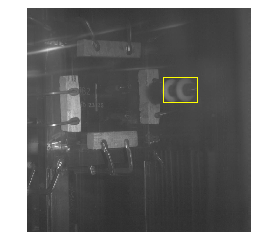

im = insertShape(im, 'Rectangle', bbox_real, 'LineWidth', 5);
imshow(im);

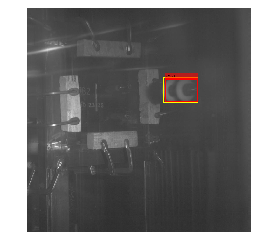


im = insertObjectAnnotation(im,'rectangle',bbox_F,score_F,'LineWidth',5,'Color','red');
imshow(im);


im = insertShape(im, 'Rectangle', bbox_Y, 'LineWidth', 5,'Color','blue');
imshow(im);